clear; clc; close all;
addpath(genpath(pwd));
addpath('../tproduct toolbox 2.0 (transform)/')

l = 5; p = 4; n = 10; m = 25;               
 
num_trials = 5;
num_its = 2000;

num_corrupt = round(0.025*(m*p*n));
num_rowcorrupt = round(0.2*m);
mean_corrupt = 10;
deviation_corrupt = 5;

q = 0.975;

Tvals = [1,2,3,4,5,6];

median_errs_matrix = zeros(6,num_its+1);
T_ind = 1;
for Tval = Tvals   
    % Initialization
    errs_matrix = zeros(num_trials, num_its+1);
    
    % Perform trials
    for t = 1:num_trials
    
        %generate tensors
        A = randn(m,l,n);
        X_true = randn(l,p,n);
        B = tprod(A,X_true);
        X0 = randn(l,p,n); 
    
        % Generate random corruption values for each trial
        corruption_values = normrnd(mean_corrupt, deviation_corrupt, [num_corrupt, 1]);
    
        % Generate k random row indices to corrupt
        corrupt_rows = randsample(m, num_rowcorrupt, false);
    
        % Distribute num_corrupt corruptions uniformly across the k rows
        for i = 1:num_corrupt
            % Select a random row from the chosen rows
            row_idx = corrupt_rows(randsample(num_rowcorrupt, 1));
    
            % Randomly select indices for the other dimensions
            col_idx = randsample(p, 1);
            depth_idx = randsample(n, 1);
    
            % Apply the corruption value
            B(row_idx, col_idx, depth_idx) = B(row_idx, col_idx, depth_idx) + corruption_values(i);
        end
       
        % Run Algorithm 
        [~, its] = batchQTRK_Algorithm(A,B, X0, num_its, q, Tval); % Adjust q as needed
        
    
        % Record errors for the current trial
        for j = 1:num_its + 1
            est = its{j} - X_true; % Adjust X_true according to your setup
            errs_matrix(t,j) = norm(est(:))/norm(X_true(:)); % Relative Frobenius error to true solution
        end
    end
    median_errs_matrix(T_ind,:) = median(errs_matrix);
    T_ind = T_ind + 1;
end

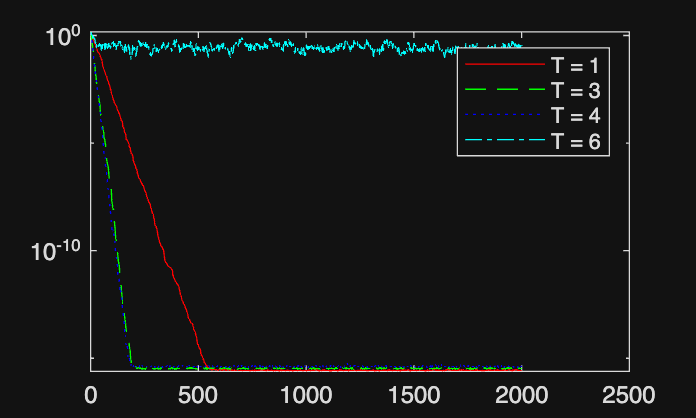

semilogy(1:num_its+1, median_errs_matrix(1,:), 'r-',1:num_its+1, median_errs_matrix(3,:),'g--', 1:num_its+1, median_errs_matrix(4,:), 'b:',1:num_its+1, median_errs_matrix(6,:),'c-.')
legend('T = 1','T = 3', 'T = 4', 'T = 6')